clear;
tic;

Central.delta = 0.01;
Central.N_UnitCell = 3;
Central.N_row = 10;
Central.N_col = 1000;
N_Disorder = 11;
N_delta = 1;
BoundaryCond = "OBC";
Central.BoundaryCond = BoundaryCond;
Central.Jdelta = 10;
Central.J = Central.Jdelta / Central.delta;
% Central.J = 1000;
Central.epsilon = 0 * ones(1,Central.N_UnitCell);
Central.mu = 0;
% 中心区其他量
% 总格点数
N_tot_site = Central.N_row * Central.N_col * Central.N_UnitCell;
N_Cells = Central.N_row * Central.N_col;
% 每列格点数
N_site_pcol = Central.N_row * Central.N_UnitCell;
% 跃迁
J_plus = Central.J*(1 + Central.delta);
J_minus = Central.J*(1 - Central.delta);
% 格点标号
A = 1; B = 2; C = 3;
eta = 1e-5;
% warning('off');
FermiEnergy = 0;

W = linspace(0,10,N_Disorder);
% delta = logspace(-4,-0.1,N_delta);
delta = 0.01;
LocLength = zeros(length(delta), length(W));
for kk = 1:length(W)
    for jj = 1:length(delta)
        Central.delta = delta(jj);
        Central.J = Central.Jdelta / Central.delta;
        J_plus = Central.J*(1 + Central.delta);
        J_minus = Central.J*(1 - Central.delta);
        if Central.N_row < 2
            [H_CC, V_CC] = Hamiltonian_Lieb_1D(Central.epsilon, J_minus, J_plus);
        else
            [H_CC, V_CC] = Lieb_2D_Hamiltonian(Central.epsilon,J_plus,J_minus,J_minus,Central.N_row, BoundaryCond);
        end
        r = rank(V_CC);
        R = eye(size(H_CC,1));
        R_Spectrum = zeros(2*r, Central.N_col);
        for ii = 1:Central.N_col
            if ii > 1
                T = Transfer_Matrix(H_CC, V_CC, FermiEnergy, W(kk))*Q;
            else
                T = Transfer_Matrix(H_CC, V_CC, FermiEnergy, W(kk));
            end
            [Q, R] = qr(T);
            [R_diag, ind] = sort(diag(R), 'descend','ComparisonMethod','abs');
            Q = Q(:, ind);
            R_Spectrum(:, ii) = abs(R_diag);
        end
        lnR = log(R_Spectrum);        
        Lyapunov_Spectrum = sum(lnR,2)/Central.N_col;        

        LocLength(jj, kk) = 1./min(abs(Lyapunov_Spectrum));
        % disp(['Lyapunov Exponent:',num2str(min(abs(Lyapunov_Spectrum)))])
        % disp(['Localization:',num2str(1./min(abs(Lyapunov_Spectrum)))])
        % figure
        % plot(1:Central.N_col, cumsum(lnR,2)./(1:Central.N_col))
        % figure
        % plot(1:Central.N_col, (1:Central.N_col)./cumsum(lnR,2))
    end
end

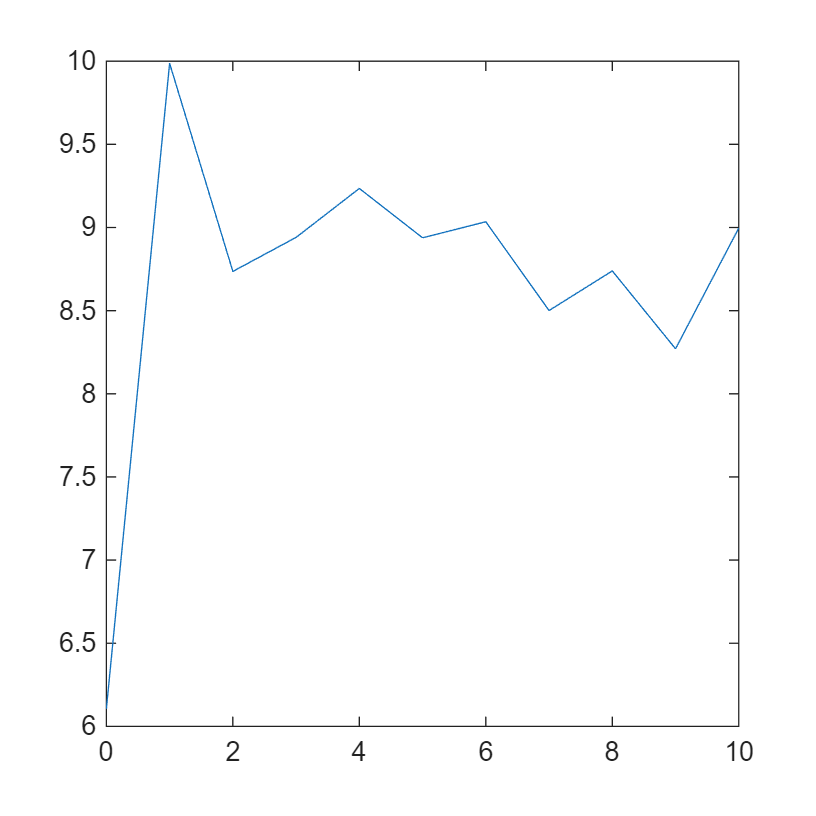

if isscalar(delta)
    plot(W, LocLength);
else
    plot(delta, LocLength, delta, (1-delta).^2./(8*delta))
    xscale log
    % yscale log
end
hold off




toc;

历时 1.701860 秒。


function T = Transfer_Matrix(H_CC, V_CC, FermiEnergy, Disorder)
eta = 1e-4;
[V, Xi, W] = svd(V_CC);
r = rank(Xi);
V = V(:, 1:r);
W = W(:, 1:r);
Xi = Xi(1:r, 1:r);
H_imp = Disorder * diag(rand(1,size(H_CC,1))-0.5);
G = inv((FermiEnergy + 1i * eta) * eye(size(H_CC,1)) - H_CC - H_imp);
G_vv = (V' * G * V) * Xi;
G_ww = (W' * G * W) * Xi;
G_vw = (W' * G * V) * Xi;
G_wv = (V' * G * W) * Xi;

theta = angle(det(G_vw));


T = [inv(G_vw), -inv(G_vw) * G_ww; 
    G_vv * inv(G_vw), G_wv - G_vv * inv(G_vw) * G_ww];
T = exp(1i * theta / r) * T;
end


function [H_00_OneCol, V] = Lieb_2D_Hamiltonian(epsilon,J_plus,J_minus_x,J_minus_y,N_row, varargin)


H_00 = [epsilon(1), J_plus, J_plus;
    J_plus, epsilon(2),0;
    J_plus, 0, epsilon(3)];
%% 原胞间跃迁

% 构造纵向跃迁元 Transition between row
H01_y = [0, 0, 0;
    0, 0, 0;
    J_minus_y, 0, 0];

H_00_OneCol = kron(eye(N_row), H_00) + kron(diag(ones(1, N_row-1),1), H01_y) + kron(diag(ones(1, N_row-1),-1), H01_y');
% 当存在额外参数时，增加纵向的周期性边界条件
if nargin > 6
    if varargin{1} == "PBC"
        if N_row > 1
            H_00_OneCol(1, end) = J_minus_y;
            H_00_OneCol(end, 1) = J_minus_y;
        end
    elseif varargin{1} == "OBC"
    else
        error("Input must be 'PBC' or 'OBC' for periodic/open boundary condition");
    end
end

% 构造横向跃迁元 Transition between column
H01_x = [0, J_minus_x, 0;
    0, 0, 0;
    0, 0, 0];

V = kron(eye(N_row), H01_x);
end


function [H00, H01] = Hamiltonian_Lieb_1D(epsilon, J_minus, J_plus)
    H00 = [epsilon(1),     J_plus, J_plus;
          J_plus,     epsilon(2),   0;
          J_plus, 0,           epsilon(3)];
    H01 = [0, J_minus, 0;
           0, 0, 0;
           J_minus, 0, 0];
end